# Beyond Raman Nath Regime

## Initialization



units % load some common physical constants
m_Li6mol = 2*m_Li6;
aLi_12 = 982*a0;
add_Li = aLi_12*0.6;

totalODTpower = 22.5;
EndODTpower = 22.5;

omegax = 81*pi*2*sqrt(EndODTpower/totalODTpower); % trap frequencies 
omegay = 3040*pi*2*sqrt(EndODTpower/totalODTpower);
omegaz = 3040*pi*2*sqrt(EndODTpower/totalODTpower);

% scale parameters
tscale = 1/(omegax); % time scale
rscale = sqrt(hbar/m_Li6mol/omegax); % spatial scale

% Lattice parameters defination
Wavelength = 1064*10^-9;

D = Wavelength/2; % Lattice period 0.532 micons
Erecoil = hbar^2*(pi/D)^2/(2*m_Li6mol); % recoil energy 

LatticePotential = 50; % lattice depth in unit of recoil energy
V = @(X,Y,Z) 0.5*(X.^2 + (omegay/omegax* Y).^2); % function representing the external potential (must have 3 arguments)


ymax = 25*D/rscale; %  grid boundaries [-xmax,xmax]
xmax = 800*D/rscale; %  grid boundaries [-xmax,xmax]
Nx = 16000; % number of grid points for coordinate grid
Ny = 500;
try
    x = gpuArray.linspace(-xmax,xmax,Nx);
    y = gpuArray.linspace(-ymax,ymax,Ny);
    grid = grid2d(x,y);
catch
    grid = grid2d(xmax,Nx,ymax,Ny); % create a two-dimensional NxN grid object
end

task = GPEtask(grid,V); % initialize the GPE solver
task.Ntotal = 3000; % wave function normalization (total number of atoms)


task.Xscale = rscale;
task.Tscale = tscale;
task.LatticeConstant = D;


## Stationary state calculation

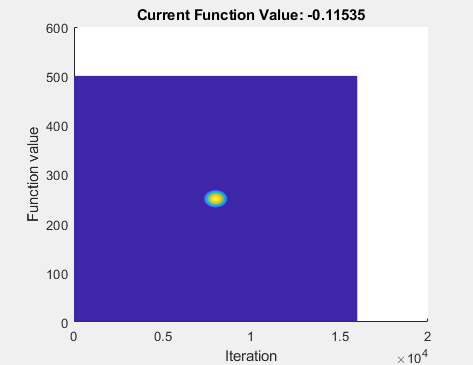


% phi = task.groundstate_itp(tstep,acc,'tf'); % phi will contain calculated stationary state
[phi,mu,R] = task.groundstate_tf_harmonic(add_Li,omegax,omegay,omegaz);

% Plot the initial state
imagesc(abs(phi).^2)


task.g = 4*pi*add_Li/rscale/sqrt(2*pi/sqrt(omegaz*omegay)*omegax); % nonlinear interaction constant


%% switch on lattice for Deltat
Deltat = 4*10^-6/tscale; % total duration for simulation; (20 mico-seconds)
tstep = 10*10^-9/tscale; % time step for calculation; (20 ns)
steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)

task.init_state = phi;
task.show_image = 0; % show the solution on every precessing step


NmaxP = 2; % maximum mode of momentum to be analyzed

% function representing the external potential (must have 3 arguments)
Vlattice = @(X,Y,Z) LatticePotential*Erecoil/(hbar*omegax)...
    *(cos((pi/D)*X*rscale).^2 + cos((pi/D)*Y*rscale).^2); 
task.UpdatePotential(Vlattice);
% task.history.MomentumDensity = [];
task.user_callback = @(x)task.FFTanalysis2D(true,NmaxP);
steps_ext = task.current_iter + Deltat/tstep/steps_int;


## start simulation

Split-step: iter - 0, mu - 0.000, calc. time - 0.890 sec.; 0 mode Proportion: 1
Split-step: iter - 1, mu - 9191.993, calc. time - 6.896 sec.; 0 mode Proportion: 0.948
Split-step: iter - 2, mu - 9192.044, calc. time - 12.384 sec.; 0 mode Proportion: 0.807
Split-step: iter - 3, mu - 9192.289, calc. time - 17.887 sec.; 0 mode Proportion: 0.612
Split-step: iter - 4, mu - 9192.974, calc. time - 23.298 sec.; 0 mode Proportion: 0.409
Split-step: iter - 5, mu - 9194.470, calc. time - 28.913 sec.; 0 mode Proportion: 0.237
Split-step: iter - 6, mu - 9197.337, calc. time - 34.926 sec.; 0 mode Proportion: 0.115
Split-step: iter - 7, mu - 9202.466, calc. time - 40.721 sec.; 0 mode Proportion: 0.0439
Split-step: iter - 8, mu - 9211.337, calc. time - 46.223 sec.; 0 mode Proportion: 0.0119
Split-step: iter - 9, mu - 9226.446, calc. time - 51.722 sec.; 0 mode Proportion: 0.00189
Split-step: iter - 10, mu - 9251.752, calc. time - 57.388 sec.; 0 mode Proportion: 0.000206
Split-step: iter - 11, mu - 9292.

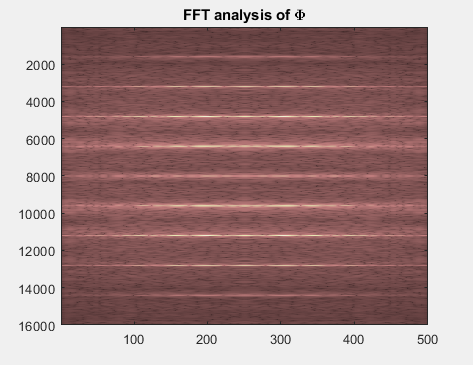

Split-step: iter - 40, mu - 9296.591, calc. time - 224.904 sec.; 0 mode Proportion: 0.0117



task.solve_split(tstep,steps_int,steps_ext); % run the calculation

## momentum modes distribution

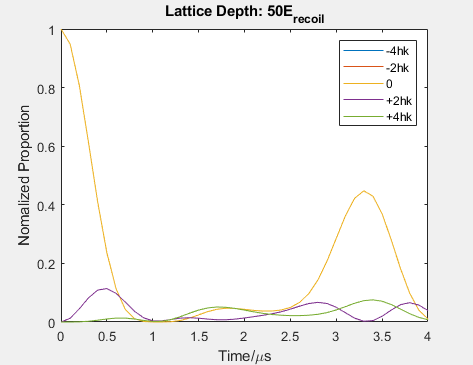


trange = (0:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,1:NmaxP*2+1,NmaxP+1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

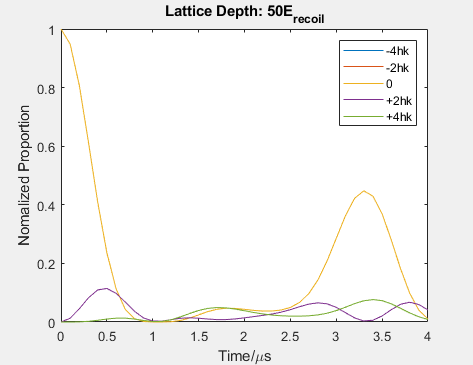

trange = (0:steps_ext)*tstep*steps_int*tscale;
MomentumDensity = Get_momentumDesity_2D( ...
    task.history.MomentumDensity,NmaxP+1,1:NmaxP*2+1);
MomentumDensity = MomentumDensity./max(MomentumDensity(:));
plot(trange*10^6, MomentumDensity(:,NmaxP-1:NmaxP+3)')
xlabel('Time/\mus')
ylabel("Nomalized Proportion")
title(['Lattice Depth: ',num2str(LatticePotential),'E_{recoil}'])
legend('-4hk','-2hk','0','+2hk','+4hk')

##  Raman-Nath regime?

For Raman-Nath regime


$$t_{\max } \frac{\sqrt{E_r U_0 }}{\hbar }<1$$


Deltat*tscale * sqrt(LatticePotential)*Erecoil/hbar

ans = 2.6034

task.whisper = 0;
options = optimoptions(@fminunc,'Display','iter','PlotFcn','optimplotfval' ,'StepTolerance',0.01);
problem.options = options;
% problem.x0 = rand(1,3);
problem.x0 = [0.1 0.5 0.4];
% problem.x0 = 4;
problem.objective = @(x) PulseSequenceEvolve(task,x);
problem.solver = 'fminunc';
task.userData.LatticeP = Vlattice;
x = fminunc(problem)

function SecondOrderMomentum = PulseSequenceEvolve(task,PulseSequenceNum)
PulseSequence = PulseSequenceNum*10^-6/task.Tscale; % duration for simulation

steps_int = 10;  % number of intenal steps. (should be larger than 10 task.n_recalc)
tstep = sum(PulseSequence)/steps_int/10; % time step for calculation;
task.show_image = 0; % show the solution on every precessing step

task.reInitialize
NmaxP = 2; % maximum mode of momentum to be analyzed
task.FFTanalysis2D(false,NmaxP);
MomentumDensityInitial = task.history.MomentumDensity{1};
task.user_callback = @(x)0;
PotentialOn = -1;
for Deltat = PulseSequence

    PotentialOn = -PotentialOn;
    if PotentialOn > 0
        % function representing the external potential (must have 3 arguments)
        Vpotential = task.userData.LatticeP; 
    else
        Vpotential = @(X,Y,Z) 0; 
    end

    task.UpdatePotential(Vpotential);
    steps_ext = task.current_iter + round( Deltat/tstep/steps_int);
    task.solve_split(tstep,steps_int,steps_ext); % run the calculation
end

task.FFTanalysis2D(false,NmaxP);
MomentumDensity = task.history.MomentumDensity{end};
MomentumDensity = MomentumDensity./max(MomentumDensityInitial(:));
SecondOrderMomentum = -MomentumDensity(NmaxP+1,NmaxP);
end